# Computer Vision

Representación de rectas 

n = [0.4, 0.2];  % vector normal en R2 
x = -2:0.01:2; 

a = n(1); b = n(2); 
y = -x * a/b; 

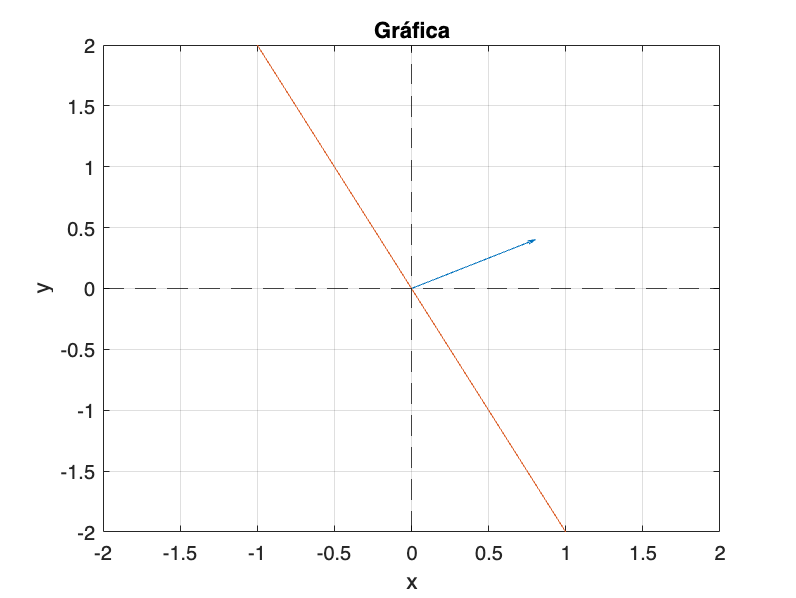

figure(); 
quiver(0, 0, n(1) / norm(n), n(2) / norm(n)); % Grafica 
hold on; 
plot(x, y); 
hold off; 


% plot info 
title("Gráfica"); 
xlabel("x"); 
ylabel("y"); 
axis([-2, 2, -2, 2]); 
grid on; 
xline(0, 'k--')
yline(0, 'k--')

## Intersección de lineas

Definiendo las rectas en coordenadas homogeneas $\tilde{l}$ podemos encontrar el punto de intersección de cualquier par de rectas como el producto cruz entre ellas: 


$$\tilde{x} =\tilde{\;l_1 } \times \tilde{l_2 }$$


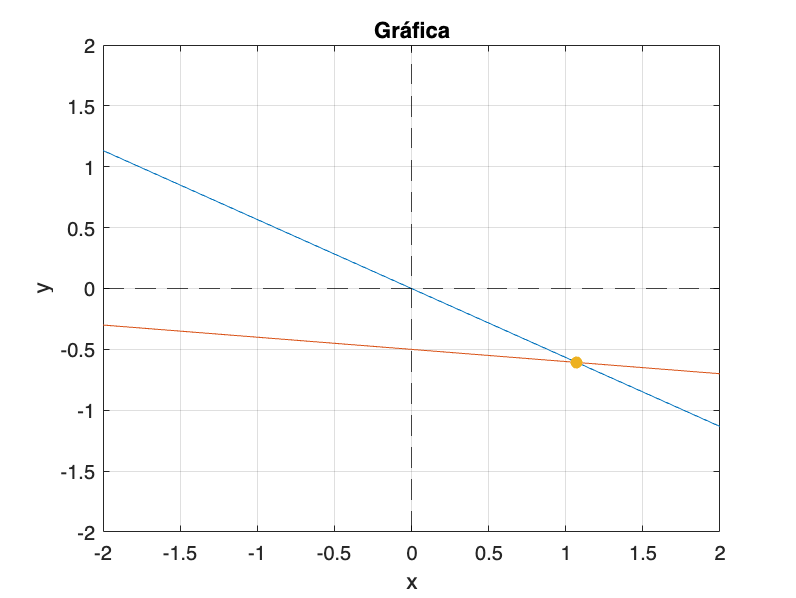

l1 = [1.7, 3, 0]; 
l2 = [0.2, 2, 1]; 

draw_line(l1);  hold on; 
draw_line(l2); 
p = cross(l1, l2); 
p = p / p(3); 
scatter(p(1), p(2), 'filled'); 
hold off ; 

title("Gráfica"); 
xlabel("x"); 
ylabel("y"); 
axis([-2, 2, -2, 2]); 
grid on; 
xline(0, 'k--')
yline(0, 'k--')

function [] = draw_line(l1)
    x = -2:0.01:2; 
    plot(x, -1/l1(2) * (x * l1(1) + l1(3))); 
end 